# Do LDE

## 0. All pars needed. Using one canonical set here

CurrentFolder = pwd
FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Figures/Demo092521/'];
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Data/LDE_Precomputing/'];
addpath(DataFolder)

First read old network structure, get our desired Numbers of presyn neurons

% load('NtWk_Archit.mat')
% E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
% [E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
% E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
% I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
% [I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
% I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);
% 
% N_EE = full(mean(sum(C_EE(E_Ind,:),2))); N_EI = full(mean(sum(C_EI(E_Ind,:),2))*0.75); %*0.75
% N_IE = full(mean(sum(C_IE(I_Ind,:),2))); N_II = full(mean(sum(C_II(I_Ind,:),2))*0.75); %*0.75 Plan A:Original

Then use the new function to generate new network stucture


%% If now, we start computation below...
% Frst setup network
N_HC = 3;
% Number of E and I neurons
n_S_HC = 45; n_C_HC = 30; n_I_HC = 31; % per side of HC
N_S = n_S_HC^2 * N_HC^2; % neuron numbers In all
N_C = n_C_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
N_E = N_S+N_C; CplxR = N_C/N_E;
% Grid sizes of E and I neurons;
Size_HC = 0.500; % in mm;
Size_S = Size_HC/n_S_HC; Size_C = Size_HC/n_C_HC; Size_I = Size_HC/n_I_HC;
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6;

% spatial indexes of E and I neurons
[NnS.X,NnS.Y] = V1Field_Generation(N_HC,1:N_S,'e',n_S_HC,n_I_HC);
[NnC.X,NnC.Y] = V1Field_Generation(N_HC,1:N_C,'e',n_C_HC,n_I_HC);
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');
%NnE.X = [NnS.X,NnC.X]; NnE.Y = [NnS.Y,NnC.Y];

We are fixing boundary effect by connecting neurons to similar ODs

% Extended spatial indexes of E and I neurons (1HC each side)
Nex_S = n_S_HC^2 * (N_HC+2)^2; % neuron numbers In all
Nex_C = n_C_HC^2 * (N_HC+2)^2; 
Nex_I = n_I_HC^2 * (N_HC+2)^2;
[NnSex.X,NnSex.Y] = V1Field_Generation(N_HC+2,1:Nex_S,'e',n_S_HC,n_I_HC);
[NnCex.X,NnCex.Y] = V1Field_Generation(N_HC+2,1:Nex_C,'e',n_C_HC,n_I_HC);
[NnIex.X,NnIex.Y] = V1Field_Generation(N_HC+2,1:Nex_I,'i');

Now select complx cells

N_EE = 193; N_EI = 85; %*0.75
N_IE = 844; N_II = 84; %*0.75 Plan A:Original

CplxNEIncr = 253/N_EE; % Was 250 for 071021 simulation
EcplxInd = ismember(1:N_E, N_S+1:N_E); 

N_SS = N_EE * (1-CplxR);            N_SC = N_EE * (CplxR); 
N_CS = N_EE * (1-CplxR)*CplxNEIncr; N_CC = N_EE * (CplxR)*CplxNEIncr;
N_SI = N_EI;                        N_CI = N_EI; 
N_IS = N_IE * (1-CplxR);            N_IC = N_IE * (CplxR); 

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.530; 
rI_amb = 0.435; % was 0.5 for for 071021 simulation

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.8;  % was 1.6 for for 071021 simulation
S_II = 0.120; S_IE = S_II*0.153 * 1.6/1.8;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
N_Slgn = 4.75; N_Clgn = 1.25; N_Ilgn = 4.5;

lambda_E = 0.02*[N_Slgn*ones(N_S,1);N_Clgn*ones(N_C,1)]; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.02*N_Ilgn; 

## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_S = zeros(size(NnS.X),'single');
OD_SMap = zeros(n_S_HC*N_HC,'single');
for NeuInd = 1:length(NnS.X)
OD_S(NeuInd) = OrientDom(ODNum,NnS.X(NeuInd),NnS.Y(NeuInd),n_S_HC);
OD_SMap(NnS.Y(NeuInd),NnS.X(NeuInd)) = OD_S(NeuInd);
end

OD_C = zeros(size(NnC.X),'single');
OD_CMap = zeros(n_C_HC*N_HC,'single');
for NeuInd = 1:length(NnC.X)
OD_C(NeuInd) = OrientDom(ODNum,NnC.X(NeuInd),NnC.Y(NeuInd),n_C_HC);
OD_CMap(NnC.Y(NeuInd),NnC.X(NeuInd)) = OD_C(NeuInd);
end
OD_E = [OD_S, OD_C];

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

### Incorporate Phase:

Use an updating vector for each E cell to reflect its on-off phase

Directly pull lgnEevents and do multiplication with the phase factor

StimulusFac = 1;
LGNFreq = 4; % 2 4 10Hz
tMod = 1e3/LGNFreq; MaxOnPhase = tMod/2;% Each Cycle lasts for 500 ms
PhaseE = single(tMod*rand(N_E,1));
PhaseFRS = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Slgn/1e3 * StimulusFac; % 4 to 5
%PhaseFRC = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Clgn/1e3 * StimulusFac;
PhaseFRC = 45*ones(1,8) *N_Clgn/1e3 * StimulusFac;
lambda_EOn_drive  = [PhaseFRS(OD_S),PhaseFRC(OD_C)]'; % Should do another for Cplx cells
lambda_EOff_drive = [PhaseFRS(OD_S+ODNum),PhaseFRC(OD_C+ODNum)]';
% T partition
T = 10000; dt = 0.1; TPar = 10;

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lambda_E_drive_Pre = 45 *N_Slgn/1e3 * StimulusFac;
lambda_I_drive_Pre = 45 *N_Ilgn/1e3 * StimulusFac;

L6E_Drive = [50 35 20 35]*50/1e3 * StimulusFac;
rE_L6_Drive = L6E_Drive(OD_E)';
rI_L6_Drive = 3*L6E_Drive(OD_I)';

## 1. Details of NW before gluing everying up

Comparisons of MF+V before LDE

load('AllMFPixPara.mat')
load('MFpVPix_New.mat')
PixNum = 900;
FrMFpV = zeros(5,PixNum);
mVMFpV = zeros(5,PixNum);
for PixInd = 1:PixNum
    FrMFpV(:,PixInd) = mean(f_EnIOut{PixInd}(:,end-25:end),2);
    mVMFpV(:,PixInd) = mean(meanVs{PixInd}(:,end-25:end),2);
end
FrSMFV = ((FrMFpV(1,:) + FrMFpV(3,:))/2)';
FrCMFV = ((FrMFpV(2,:) + FrMFpV(4,:))/2)';
FrIMFV = (FrMFpV(5,:))';
%mVSMFV = ((mVMFpV(1,:) + mVMFpV(3,:))/2)';
mVCMFV = ((mVMFpV(2,:) + mVMFpV(4,:))/2)';
mVIMFV = (mVMFpV(5,:))';

% Connectivity within Pixels 
% C_PQ_Pixel: Average number of presyn neurons from pixel j to i
N_PreSynPixIn = ...
    [mean(diag(C_SS_Pixel_Us)),mean(diag(C_CS_Pixel_Us)),mean(diag(C_IS_Pixel_Us));
     mean(diag(C_SC_Pixel_Us)),mean(diag(C_CC_Pixel_Us)),mean(diag(C_IC_Pixel_Us));
     mean(diag(C_SI_Pixel_Us)),mean(diag(C_CI_Pixel_Us)),mean(diag(C_II_Pixel_Us))];
N_PreSynPixInStd = ...
    [std(diag(C_SS_Pixel_Us)),std(diag(C_CS_Pixel_Us)),std(diag(C_IS_Pixel_Us));
     std(diag(C_SC_Pixel_Us)),std(diag(C_CC_Pixel_Us)),std(diag(C_IC_Pixel_Us));
     std(diag(C_SI_Pixel_Us)),std(diag(C_CI_Pixel_Us)),std(diag(C_II_Pixel_Us))];

% From Outside the Pixels
C_SSO = sum(C_SS_Pixel_Us-diag(diag(C_SS_Pixel_Us)),2);
C_CSO = sum(C_CS_Pixel_Us-diag(diag(C_CS_Pixel_Us)),2);
C_ISO = sum(C_IS_Pixel_Us-diag(diag(C_IS_Pixel_Us)),2);
C_SCO = sum(C_SC_Pixel_Us-diag(diag(C_SC_Pixel_Us)),2);
C_CCO = sum(C_CC_Pixel_Us-diag(diag(C_CC_Pixel_Us)),2);
C_ICO = sum(C_IC_Pixel_Us-diag(diag(C_IC_Pixel_Us)),2);
C_SIO = sum(C_SI_Pixel_Us-diag(diag(C_SI_Pixel_Us)),2);
C_CIO = sum(C_CI_Pixel_Us-diag(diag(C_CI_Pixel_Us)),2);
C_IIO = sum(C_II_Pixel_Us-diag(diag(C_II_Pixel_Us)),2);
N_PreSynPixOut = ...
    [mean(C_SSO),mean(C_CSO),mean(C_ISO);
     mean(C_SCO),mean(C_CCO),mean(C_ICO);
     mean(C_SIO),mean(C_CIO),mean(C_IIO)];
N_PreSynPixOutStd = ...
    [std(C_SSO),std(C_CSO),std(C_ISO);
     std(C_SCO),std(C_CCO),std(C_ICO);
     std(C_SIO),std(C_CIO),std(C_IIO)];

% 3 ODs
OPTPix = lambda_SOn_Pixel>0.42;
OBLPix = lambda_SOn_Pixel>0.30 & lambda_SOn_Pixel<0.33;
ORTPix = lambda_SOn_Pixel<0.22;
OPTOBLBd_Pix = lambda_SOn_Pixel>0.33 & lambda_SOn_Pixel<0.42;
ORTOBLBd_Pix = lambda_SOn_Pixel>0.22 & lambda_SOn_Pixel<0.30;
% Compute averaged FrE
NSPix = N_S/PixNum; NCPix = N_C/PixNum;
FrEPixNW = (FrSPixVec*NSPix + FrCPixVec*NCPix)/(NSPix+NCPix);
FrEPixMF = (FrSMFV*NSPix + FrCMFV*NCPix)/(NSPix+NCPix);

Load LDE computations and do Fr distributions

fLDE_OPT = load('MFpV_LDE_3.mat','f_EnIOut'); fLDE_OPT = fLDE_OPT.f_EnIOut;
fLDE_OBL = load('MFpV_LDE_2.mat','f_EnIOut'); fLDE_OBL = fLDE_OBL.f_EnIOut;
fLDE_ORT = load('MFpV_LDE_1.mat','f_EnIOut'); fLDE_ORT = fLDE_ORT.f_EnIOut;
FrLDE_opt = zeros(5,length(fLDE_OPT));
FrLDE_obl = zeros(5,length(fLDE_OPT));
FrLDE_ort = zeros(5,length(fLDE_OPT));
for LDEInd = 1:length(fLDE_OPT)
    if ~isempty(fLDE_OPT{LDEInd})
        FrLDE_opt(:,LDEInd) = mean(fLDE_OPT{LDEInd}(:,end-25:end),2);
        FrLDE_obl(:,LDEInd) = mean(fLDE_OBL{LDEInd}(:,end-25:end),2);
        FrLDE_ort(:,LDEInd) = mean(fLDE_ORT{LDEInd}(:,end-25:end),2);
    else
        FrLDE_opt(:,LDEInd) = nan;
        FrLDE_obl(:,LDEInd) = nan;
        FrLDE_ort(:,LDEInd) = nan;
    end
end
FrLDE_optE = ((FrLDE_opt(1,:)+FrLDE_opt(3,:))/2 * NSPix + ...
              (FrLDE_opt(2,:)+FrLDE_opt(4,:))/2 * NCPix)/(NSPix+NCPix);
FrLDE_oblE = ((FrLDE_obl(1,:)+FrLDE_obl(3,:))/2 * NSPix + ...
              (FrLDE_obl(2,:)+FrLDE_obl(4,:))/2 * NCPix)/(NSPix+NCPix);
FrLDE_ortE = ((FrLDE_ort(1,:)+FrLDE_ort(3,:))/2 * NSPix + ...
              (FrLDE_ort(2,:)+FrLDE_ort(4,:))/2 * NCPix)/(NSPix+NCPix);
% Do hist2
XOPT = linspace(12,51,30); YOPT = linspace(45,143,30);
NW_OPT = histcounts2(FrEPixNW(OPTPix),FrIPixVec(OPTPix),XOPT,YOPT);
LDE_OPT = histcounts2(FrLDE_optE,FrLDE_opt(5,:),XOPT,YOPT);
XOBL = linspace(5,32,30); YOBL = linspace(27,114,30);
NW_OBL = histcounts2(FrEPixNW(OBLPix),FrIPixVec(OBLPix),XOBL,YOBL);
LDE_OBL = histcounts2(FrLDE_oblE,FrLDE_obl(5,:),XOBL,YOBL);
XORT = linspace(2,20,30); YORT = linspace(14,92,30);
NW_ORT = histcounts2(FrEPixNW(ORTPix),FrIPixVec(ORTPix),XORT,YORT);
LDE_ORT = histcounts2(FrLDE_ortE,FrLDE_ort(5,:),XORT,YORT);


Figures for comparison

figure('Name','FrRanges')
subplot 131
hold on
scatter(FrLDE_optE,FrLDE_opt(5,:),'g.','DisplayName','LDE')
scatter(FrEPixNW(OPTPix),FrIPixVec(OPTPix),'b.','DisplayName','Network')
scatter(FrEPixMF(OPTPix),FrIMFV(OPTPix),'r.','DisplayName','MF+V')
legend
xlabel('FrE');ylabel('FrI');
title('OPT')

subplot 132
hold on
scatter(FrLDE_oblE,FrLDE_obl(5,:),'g.')
scatter(FrEPixNW(OBLPix),FrIPixVec(OBLPix),'b.')
scatter(FrEPixMF(OBLPix),FrIMFV(OBLPix),'r.')
xlabel('FrE');ylabel('FrI');
title('OBL')

subplot 133
hold on
scatter(FrLDE_ortE,FrLDE_ort(5,:),'g.')
scatter(FrEPixNW(ORTPix),FrIPixVec(ORTPix),'b.')
scatter(FrEPixMF(ORTPix),FrIMFV(ORTPix),'r.')
xlabel('FrE');ylabel('FrI');
title('ORT')

figure("Name",'FrDistb')
subplot 231
imagesc((XOPT(1:end-1)+XOPT(2:end))/2,(YOPT(1:end-1)+YOPT(2:end))/2,NW_OPT')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW OPT')
subplot 234
imagesc((XOPT(1:end-1)+XOPT(2:end))/2, (YOPT(1:end-1)+YOPT(2:end))/2, LDE_OPT')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE OPT')
subplot 232
imagesc((XOBL(1:end-1)+XOBL(2:end))/2, (YOBL(1:end-1)+YOBL(2:end))/2, NW_OBL')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW OBL')
subplot 235
imagesc((XOBL(1:end-1)+XOBL(2:end))/2, (YOBL(1:end-1)+YOBL(2:end))/2,LDE_OBL')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE OBL')
subplot 233
imagesc((XORT(1:end-1)+XORT(2:end))/2, (YORT(1:end-1)+YORT(2:end))/2,NW_ORT')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW ORT')
subplot 236
imagesc((XORT(1:end-1)+XORT(2:end))/2, (YORT(1:end-1)+YORT(2:end))/2,LDE_ORT')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE ORT')

## 2. Set up LDE firing rate functions

from HPC LDE computed results

% Determine L4 Input from a range
% Expectation of kick numbers received by 1 neuron in each type
L4SE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4SI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4IE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4II = zeros(N_HC*NPixX*N_HC*NPixY,1);
for PInd = 1:N_HC*NPixX*N_HC*NPixY
L4SE(PInd) = (C_SS_Pixel_Us(PInd,:)*FrSPixVec          + C_SC_Pixel_Us(PInd,:)*FrCPixVec)...
            - C_SS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_SC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
L4SI(PInd) =  C_SI_Pixel_Us(PInd,:)*FrIPixVec - C_SI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
L4CE(PInd) = (C_CS_Pixel_Us(PInd,:)*FrSPixVec          + C_CC_Pixel_Us(PInd,:)*FrCPixVec)...
            - C_CS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_CC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
L4CI(PInd) =  C_CI_Pixel_Us(PInd,:)*FrIPixVec - C_CI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
L4IE(PInd) = (C_IS_Pixel_Us(PInd,:)*FrSPixVec          + C_IC_Pixel_Us(PInd,:)*FrCPixVec)...
            - C_IS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_IC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
L4II(PInd) =  C_II_Pixel_Us(PInd,:)*FrIPixVec - C_II_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
end
% Proportions between the distributions of kicks to SCI cells
% Assumption here: Total kicks received by the same pixel should be
% proportional to SCI
L4Eall = L4SE+L4CE+L4IE; L4Iall = L4SI+L4CI+L4II;
L4SEp = mean(L4SE./L4Eall);L4CEp = mean(L4CE./L4Eall);L4IEp = mean(L4IE./L4Eall);
L4SIp = mean(L4SI./L4Iall);L4CIp = mean(L4CI./L4Iall);L4IIp = mean(L4II./L4Iall);
LineFit = polyfit(L4Eall,L4Iall,1);
YRange = L4Iall - (LineFit(1)*L4Eall+LineFit(2)); % We plan to use 2 times of the range
Bdry = floor(max(abs(YRange))/100)*100;

L4ERange = 0:200:ceil(max(L4Eall)*2/100)*100;
L4IDiffRange = -12*Bdry:200:12*Bdry;
a1 = length(L4ERange); a2 = length(L4IDiffRange);

load(['MFpV_LDE_1.mat'])
figure('Name','LDERateFunctions')
CtgrName = {'Orthogonal','Intemediate','Optimal'};
LDEFrVecS = zeros(length(L4ERcrd),3);
LDEFrVecC = zeros(length(L4ERcrd),3);
LDEFrVecI = zeros(length(L4ERcrd),3);
for Ctgr = 1:3
    load(['MFpV_LDE_' num2str(Ctgr) '.mat'])
    L4EPlot = reshape(L4ERcrd,a2,a1);
    L4IPlot = reshape(L4IRcrd,a2,a1);
    FrLDE = zeros(length(f_EnIOut),5);
    for LDEInd = 1:length(f_EnIOut)
        if ~isempty(f_EnIOut{LDEInd})
            FrLDE(LDEInd,:) = (mean(f_EnIOut{LDEInd}(:,end-25:end),2))';
        else
            FrLDE(LDEInd,:) = nan;
        end
    end
    % S rates
    subplot(3,3,(Ctgr-1)*3+1)
    LDEFrVecS(:,Ctgr) = ...
    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'S',true);
    
    % C rates
    subplot(3,3,(Ctgr-1)*3+2)
    LDEFrVecC(:,Ctgr) = ...
    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'C',true); 
    
    % I rates
    subplot(3,3,(Ctgr-1)*3+3)
    LDEFrVecI(:,Ctgr) = ...
    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'I',true); 
end


Create a function

L4EfuncX = linspace(min(L4ERcrd),max(L4ERcrd),400); 
L4IfuncY = linspace(min(L4IPlot,[],'all'),max(L4IPlot,[],'all'),300);
[L4EmeshX, L4ImeshY] = meshgrid(L4EfuncX,L4IfuncY);
% 2D function now, depending on input of total E and I kick numbers
LDEFrfunc.S.ORT = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,1),L4EmeshX, L4ImeshY);
LDEFrfunc.S.OBL = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,2),L4EmeshX, L4ImeshY);
LDEFrfunc.S.OPT = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,3),L4EmeshX, L4ImeshY);
LDEFrfunc.C.ORT = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,1),L4EmeshX, L4ImeshY);
LDEFrfunc.C.OBL = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,2),L4EmeshX, L4ImeshY);
LDEFrfunc.C.OPT = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,3),L4EmeshX, L4ImeshY);
LDEFrfunc.I.ORT = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,1),L4EmeshX, L4ImeshY);
LDEFrfunc.I.OBL = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,2),L4EmeshX, L4ImeshY);
LDEFrfunc.I.OPT = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,3),L4EmeshX, L4ImeshY);

Maybe linear extrapolation?

## 3. Now Start Iteration

First, get an averaged Fr integration kernal

Write a function to smooth the integration kernel

C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,NPixX,NPixY);
C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,NPixX,NPixY);
C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,NPixX,NPixY);
C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,NPixX,NPixY);
C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,NPixX,NPixY);
C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,NPixX,NPixY);
C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,NPixX,NPixY);
C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,NPixX,NPixY);
C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,NPixX,NPixY);
% Classify Input for each pixel
PixCtgr = ORTPix + 2*OBLPix + 3*OPTPix + 4*ORTOBLBd_Pix + 5*OPTOBLBd_Pix;
PixCtgrBool = [ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix];
figure('Name','function applying')
ShowField(PixCtgr,1:900,30,30)
CtgrMap = [0,0,0.5; 0.5,0,0; 0,0.5,0; 1,0,1; 1,1,0];
cbr = colorbar; cbr.Ticks = 1:5; cbr.TickLabels = {'ORT','OBL','OPT','Bdry12','Bdry23'};
colormap(CtgrMap)

Give an intial condition, Now start

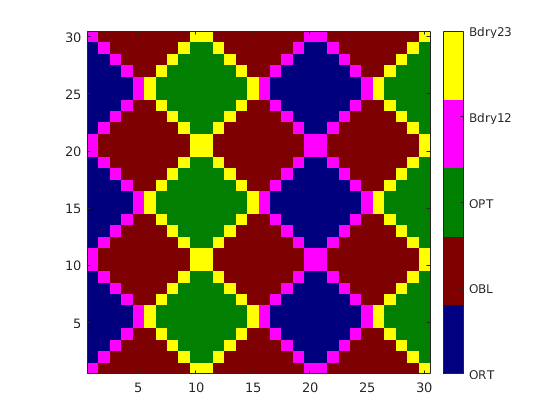

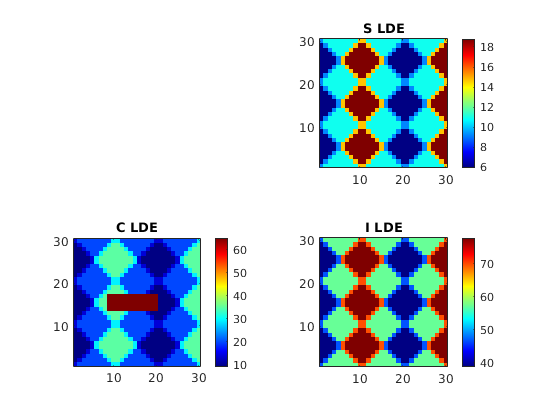

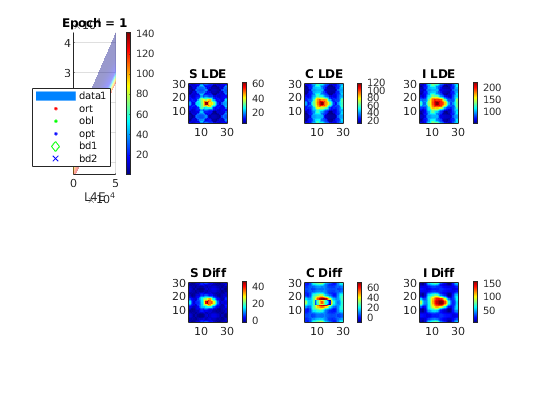

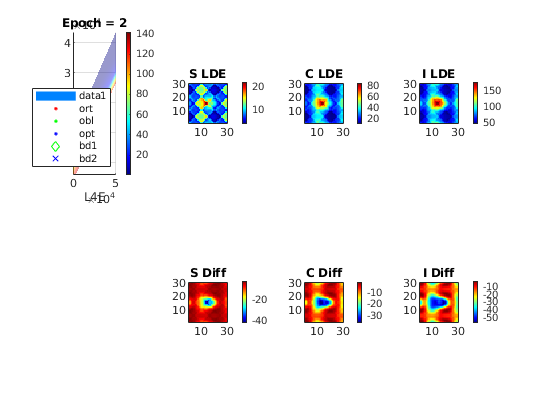

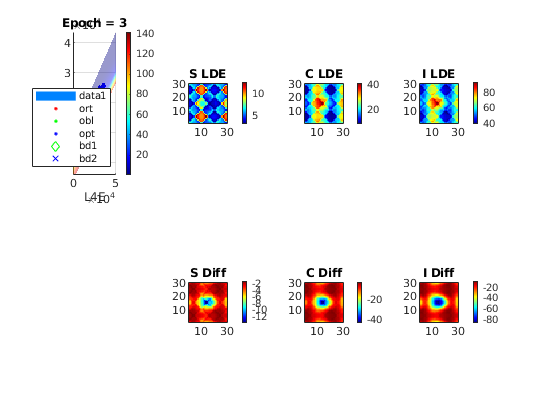

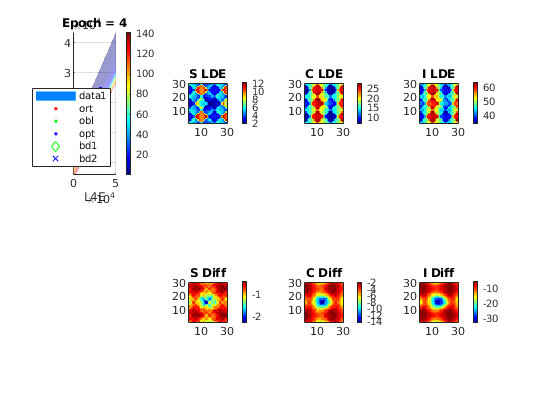

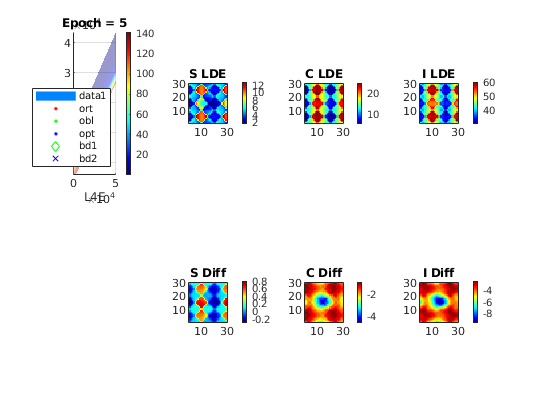

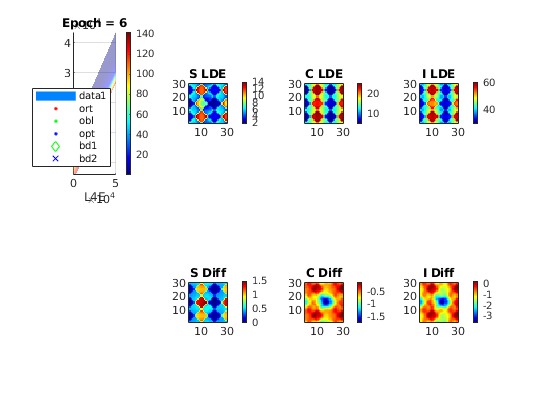

LDEIni.S = ORTPix*mean(FrSPixVec(ORTPix)) + OBLPix*mean(FrSPixVec(OBLPix)) + ...
           OPTPix*mean(FrSPixVec(OPTPix)) + ORTOBLBd_Pix*mean(FrSPixVec(ORTOBLBd_Pix)) + ...
           OPTOBLBd_Pix*mean(FrSPixVec(OPTOBLBd_Pix));
LDEIni.C = ORTPix*mean(FrCPixVec(ORTPix)) + OBLPix*mean(FrCPixVec(OBLPix)) + ...
           OPTPix*mean(FrCPixVec(OPTPix)) + ORTOBLBd_Pix*mean(FrCPixVec(ORTOBLBd_Pix)) + ...
           OPTOBLBd_Pix*mean(FrCPixVec(OPTOBLBd_Pix));
LDEIni.I = ORTPix*mean(FrIPixVec(ORTPix)) + OBLPix*mean(FrIPixVec(OBLPix)) + ...
           OPTPix*mean(FrIPixVec(OPTPix)) + ORTOBLBd_Pix*mean(FrIPixVec(ORTOBLBd_Pix)) + ...
           OPTOBLBd_Pix*mean(FrIPixVec(OPTOBLBd_Pix));
 
for IndX = 9:20
    for IndY = 14:17
        PixInd = (IndX-1)*30 + IndY;
        LDEIni.C(PixInd) = 65;
    end
end
% LDEIni.S = ones(size(LDEIni.S))*mean(LDEIni.S,'all')*2/3;
% LDEIni.C = ones(size(LDEIni.C))*mean(LDEIni.C,'all')*2/3;
% LDEIni.I = ones(size(LDEIni.I))*mean(LDEIni.I,'all')*2/3;
% LDEIni.S = FrSPixVec;
% LDEIni.C = FrCPixVec;
% LDEIni.I = FrIPixVec;
% Iteration
p = 0.2; % 1-p for the original input
Epoc = 20;
LDEItr = cell(Epoc+1,1);LDEItr{1} = LDEIni;
LDEEpoOut = cell(Epoc+1,1); LDEEpoOut{1} = LDEIni;
figure('Name','LDE Initial')
subplot 222
ShowField(LDEIni.S,1:PixNum,N_HC*NPixX,N_HC*NPixY,'S LDE')
subplot 223
ShowField(LDEIni.C,1:PixNum,N_HC*NPixX,N_HC*NPixY,'C LDE')
subplot 224
ShowField(LDEIni.I,1:PixNum,N_HC*NPixX,N_HC*NPixY,'I LDE')
for Epc = 1:Epoc
    figure('Name','LDE Iteration')
    LDEUse = LDEItr{Epc};
    L4EUse = C_SS_mean*LDEUse.S  - diag(C_SS_mean).*LDEUse.S + ...
             C_CS_mean*LDEUse.S  - diag(C_CS_mean).*LDEUse.S + ...
             C_IS_mean*LDEUse.S  - diag(C_IS_mean).*LDEUse.S + ...
             C_SC_mean*LDEUse.C  - diag(C_SC_mean).*LDEUse.C + ...
             C_CC_mean*LDEUse.C  - diag(C_CC_mean).*LDEUse.C + ...
             C_IC_mean*LDEUse.C  - diag(C_IC_mean).*LDEUse.C ;    
    L4IUse = C_SI_mean*LDEUse.I  - diag(C_SI_mean).*LDEUse.I + ...
             C_CI_mean*LDEUse.I  - diag(C_CI_mean).*LDEUse.I + ...
             C_II_mean*LDEUse.I  - diag(C_II_mean).*LDEUse.I ;
    % See where does the input stands
    subplot 241
    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'S',true,false);
    hold on
    scatter(L4EUse(ORTPix),L4IUse(ORTPix),'r.','Displayname','ort');
    scatter(L4EUse(OBLPix),L4IUse(OBLPix),'g.','Displayname','obl');
    scatter(L4EUse(OPTPix),L4IUse(OPTPix),'b.','Displayname','opt');
    scatter(L4EUse(ORTOBLBd_Pix),L4IUse(ORTOBLBd_Pix),'gd','Displayname','bd1');
    scatter(L4EUse(OPTOBLBd_Pix),L4IUse(OPTOBLBd_Pix),'bx','Displayname','bd2');
    legend('Location','southeast')
    title(sprintf('Epoch = %d', Epc))
    hold off
    % Refer to functions
    LDEOut = struct('S',[],'C',[],'I',[]);
    LDEOut.S = LDEIterFunc(L4EmeshX, L4ImeshY,...
                           LDEFrfunc.S.ORT,LDEFrfunc.S.OBL,LDEFrfunc.S.OPT,...
                           L4EUse,L4IUse,LDEUse.S,...
                           ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.C = LDEIterFunc(L4EmeshX, L4ImeshY,...
                           LDEFrfunc.C.ORT,LDEFrfunc.C.OBL,LDEFrfunc.C.OPT,...
                           L4EUse,L4IUse,LDEUse.C,...
                           ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.I = LDEIterFunc(L4EmeshX, L4ImeshY,...
                           LDEFrfunc.I.ORT,LDEFrfunc.I.OBL,LDEFrfunc.I.OPT,...
                           L4EUse,L4IUse,LDEUse.I,...
                           ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDENext = struct('S',LDEOut.S*p + LDEUse.S*(1-p),...
                     'C',LDEOut.C*p + LDEUse.C*(1-p),...
                     'I',LDEOut.I*p + LDEUse.I*(1-p));
    LDEItr{Epc+1} = LDENext; LDEEpoOut{Epc+1} = LDEOut;
    subplot 242
    ShowField(LDEOut.S,1:PixNum,N_HC*NPixX,N_HC*NPixY,'S LDE')
    subplot 243
    ShowField(LDEOut.C,1:PixNum,N_HC*NPixX,N_HC*NPixY,'C LDE')
    subplot 244
    ShowField(LDEOut.I,1:PixNum,N_HC*NPixX,N_HC*NPixY,'I LDE')
    subplot 246
    ShowField(LDEEpoOut{Epc+1}.S - LDEEpoOut{Epc}.S,1:PixNum,N_HC*NPixX,N_HC*NPixY,'S Diff')
    subplot 247
    ShowField(LDEEpoOut{Epc+1}.C - LDEEpoOut{Epc}.C,1:PixNum,N_HC*NPixX,N_HC*NPixY,'C Diff')
    subplot 248
    ShowField(LDEEpoOut{Epc+1}.I - LDEEpoOut{Epc}.I,1:PixNum,N_HC*NPixX,N_HC*NPixY,'I Diff')
    drawnow
    pause(0.5)
end